clf;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
%low pass / high pass
tf1 = tf([1],[1,1]);
tf2 = tf([1,0],[1,1]);

% %low pass / high pass
% tf1 = tf([1,1],[1])
% tf2 = tf([1,1],[1,0])

Wp = tf([1/1.5, 0.25], [1, 0.25*1e-3]);

plot weights

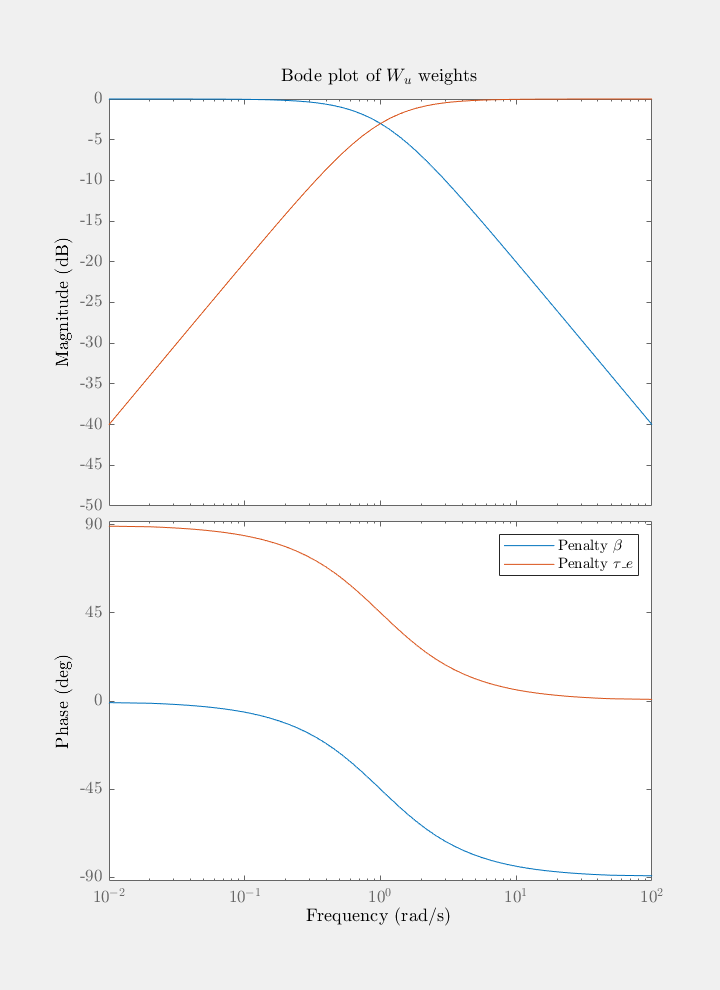

bode(tf1)
hold on
bode(tf2)
legend("Penalty $\beta$", "Penalty ${\tau}_{e}$")
xlabel('Frequency','interpreter', 'latex')
ylabel('Phase','interpreter', 'latex')
title('Bode plot of $W_u$ weights','interpreter', 'latex')
saveas(gcf, 'Figures/ch3_mimo_weights_filter_u.eps',  'epsc')

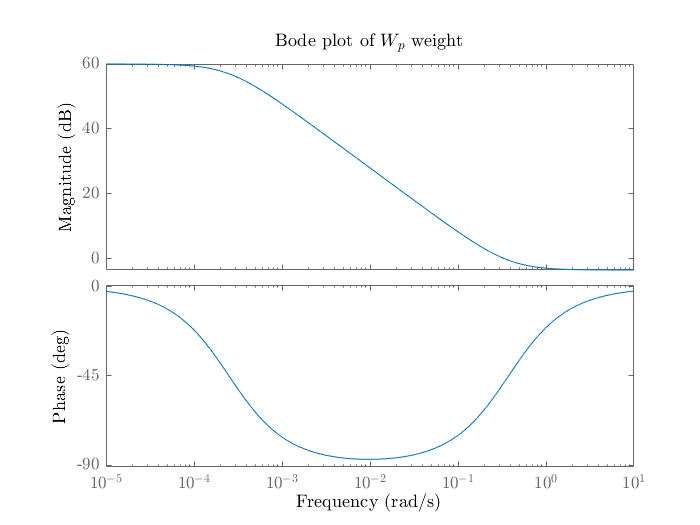


figure()
bode(Wp)
xlabel('Frequency','interpreter', 'latex')
ylabel('Phase','interpreter', 'latex')
title('Bode plot of $W_p$ weight','interpreter', 'latex')
saveas(gcf, 'Figures/ch3_mimo_weights_filter_p.eps',  'epsc')

execute H_inf synthesis

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1,1:2));


Wu = [tf1 0; 0 tf2];
P11=[Wp; zeros(size(Wu,2),size(Wp,1))]; P12=[Wp*(G); Wu]; P21=eye(size(Wp)); P22=G;
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 1, 2); %2 inputs, 2 outputs


H_inf_norm_CL = gamma

H_inf_norm_CL = 3.0655



%define inputnames of K
K.InputName = {'dOmega'}

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1     -0.00025  -3.307e-14  -4.948e-15  -9.078e-14  -7.805e-14  -3.762e-14  -1.575e-12  -1.605e-14  -2.393e-15
   x2    4.631e+05  -2.154e+04       -3228  -5.914e+04  -5.086e+04  -2.451e+04  -1.026e+06  -1.045e+04       -1558
   x3    1.467e-13           4  -1.021e-15  -1.873e-14   -1.61e-14   -7.76e-15  -3.249e-13  -3.312e-15  -4.935e-16
   x4   -3.364e-13   1.564e-14           1   4.294e-14   3.692e-14    1.78e-14   7.451e-13   7.594e-15   1.132e-15
   x5   -7.483e-14    3.48e-15   5.207e-16         0.5   8.213e-15   3.959e-15   1.657e-13   1.689e-15   2.518e-16
   x6     8.69e-14  -4.041e-15  -6.047e-16  -1.109e-14        0.25  -4.597e-15  -1.925e-13  -1.962e-15  -2.924e-16
   x7    9.159e-13  -4.259e-14  -6.373e-15  -1.169e-13  -1.005e-13    0.007812  -2.029e-12  -2.068e-14  -3.082e-15
   x8        17.53     -0.8151     -0.1221      -2.238      -1.925 

K.OutputName = {'Beta (deg)'; 'tau_e (Nm)'}

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1     -0.00025  -3.307e-14  -4.948e-15  -9.078e-14  -7.805e-14  -3.762e-14  -1.575e-12  -1.605e-14  -2.393e-15
   x2    4.631e+05  -2.154e+04       -3228  -5.914e+04  -5.086e+04  -2.451e+04  -1.026e+06  -1.045e+04       -1558
   x3    1.467e-13           4  -1.021e-15  -1.873e-14   -1.61e-14   -7.76e-15  -3.249e-13  -3.312e-15  -4.935e-16
   x4   -3.364e-13   1.564e-14           1   4.294e-14   3.692e-14    1.78e-14   7.451e-13   7.594e-15   1.132e-15
   x5   -7.483e-14    3.48e-15   5.207e-16         0.5   8.213e-15   3.959e-15   1.657e-13   1.689e-15   2.518e-16
   x6     8.69e-14  -4.041e-15  -6.047e-16  -1.109e-14        0.25  -4.597e-15  -1.925e-13  -1.962e-15  -2.924e-16
   x7    9.159e-13  -4.259e-14  -6.373e-15  -1.169e-13  -1.005e-13    0.007812  -2.029e-12  -2.068e-14  -3.082e-15
   x8        17.53     -0.8151     -0.1221      -2.238      -1.925 

dOmega_sum = sumblk('dOmega = r - Omega (rad/s)');

reference tracking of $\omega_r$ and disturbance rejection of V

%build closed loop transfer function

%first connect sum block with K by connecting inputs and outputs
%the new model has inputs [r,Omega,z] and outputs [beta, tau]
ref_tf = connect(dOmega_sum, -K,  {'r';'Omega (rad/s)'},{'Beta (deg)';'tau_e (Nm)'});
%these outputs are connected as inputs of the plant
%the inputs of the connected system are the exogenous inputs [r,V]
%we would like to monitor [r,z,Omega,tau,V], so these are the chosen outputs
outputs_ = {'r';'V (m/s)';'Omega (rad/s)'; 'z (m)';'Beta (deg)';'tau_e (Nm)'}

outputs_ = 6×1 cell array
    {'r'            }
    {'V (m/s)'      }
    {'Omega (rad/s)'}
    {'z (m)'        }
    {'Beta (deg)'   }
    {'tau_e (Nm)'   }


closed_loop = connect(ref_tf, FWT, {'r';'V (m/s)'}, outputs_);
closed_loop = minreal(closed_loop);

4 states removed.



clf

figsize = [0,0,6,4 *6]

figsize =      0     0     6    24


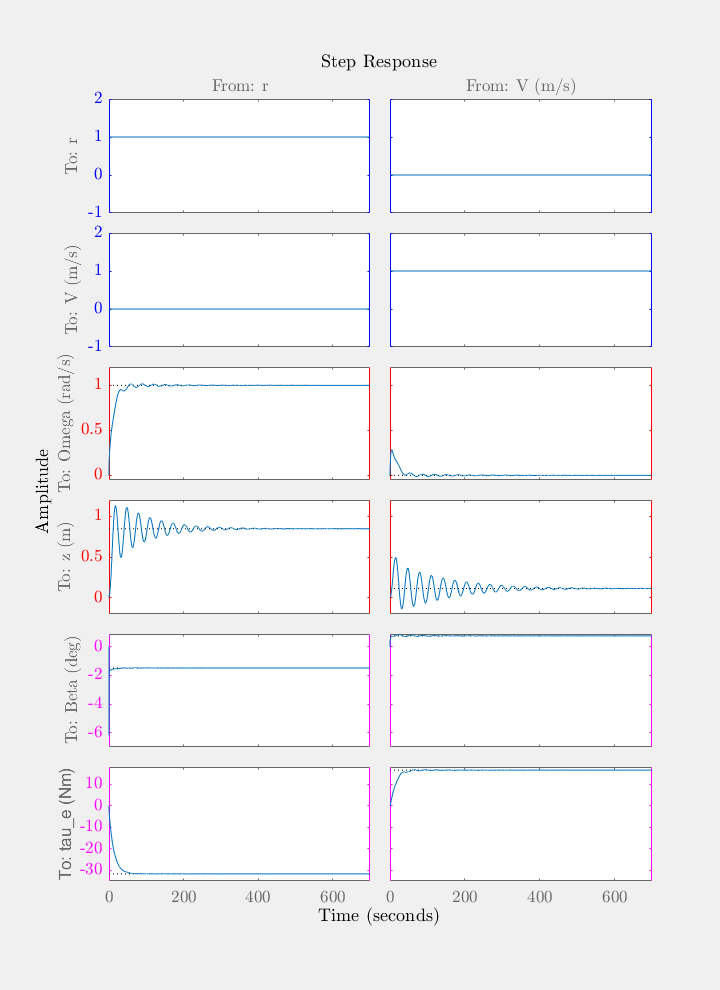


figure('units','inch','position',figsize);

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
step(closed_loop)
%[Y_sim, T_sim] = step(closed_loop);
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');

%exogenous inputs
axs(12).YColor='Blue';
axs(13).YColor='Blue';
axs(7).YColor='Blue';
axs(6).YColor='Blue';

%outputs
axs(11).YColor='Red';
axs(10).YColor='Red';
axs(5).YColor='Red';
axs(4).YColor='Red';

%control inputs
axs(9).YColor='Magenta';
axs(8).YColor='Magenta';
axs(3).YColor='Magenta';
axs(2).YColor='Magenta';

set(gcf,'Visible','on')
xlabel('Time',"interpreter",'latex')
ylabel('Amplitude',"interpreter",'latex')
for i_ax = 7:13
    axs(i_ax).YLabel.Interpreter = 'latex';
end
hs = findall(gcf, 'type', 'axes');
for i= 1:length(hs)
    ha = get(hs(i), 'title');
    ha.Interpreter = 'latex';
end

saveas(gcf, 'Figures/ch2_mimo_simulation.eps',  'epsc')